# Performance of implementations of loop orderings with outer loop indexed with "I"

## This Live Script

This Live Script helps you visualize the performance of implementations that order the loops so that the "J" loop is the outer-most loop:  Gemm_IJP.c, Gemm_IPJ.c, Gemm_dgemv.c, Gemm_bli_dgemv.c.

To gather the performance data, in the command (terminal) window change the directory to LAFF-On-HPC/Assignments/Week1/C/.  After implementing the various versions,  execute 

       make IJP  (actually, you probably did this one already)

       make IPJ

       make I_dgemv

       make I_bli_dgemv

or, alternatively, 

      make Plot_Outer_I

This compiles and executes a driver routine (the source of which is in driver.c) that collects accuracy and performance data for the various implementations.  

When completed, various data is in output file 'output_XYZ.m' (for XYZ $$ \in $$ {IJP, IPJ, ...}) in the same directory where you found this Live Script (LAFF-On-HPC/Assignments/Week1/C/data/).  This Life Script then creates graphs from that timing data.  Go ahead and click on "Run All".  It executes all the code in the rest of this file.  You will want to look at the graphs this creates.

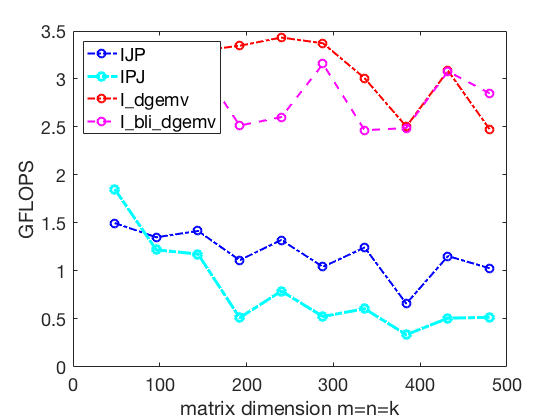

plot_colors = [ 0 0 0; 0 0 1; 0 1 0; 0 1 1; 1 0 0; 1 0 1; 1 1 0; 1 1 1];

% Create figure
figure1 = figure('Name','GFLOPS');

% Create axes, labels, legends.  In future routines for plotting performance, 
% the next few lines will be hidden in the script.
axes2 = axes('Parent',figure1);
hold(axes2,'on');
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );
box(axes2,'on');
set( axes2, 'FontName', 'Helvetica Neue', 'FontSize', 18);
             
% Plot time data for IJP 
output_IJP   % load data for JPI ordering
assert( max(abs(data(:,6))) < 1.0e-10, ...
    'Hmmm, better check if there is an accuracy problem');
plot( data(:,1), data(:,5), 'DisplayName', 'IJP', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 2,: ) );

% Plot time data for IPJ  (to plot change "0" to "1")
if ( 1 ) 
  output_IPJ
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'IPJ', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 4,: ) );
end

% Plot time data for I_dgemv  (to plot change "0" to "1")
if ( 1 ) 
  output_I_dgemv
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'I\_dgemv', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 5,: ) );
end

% Plot time data for I_bli_dgemv  (to plot change "0" to "1")
if ( 1 ) 
  output_I_bli_dgemv
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'I\_bli\_dgemv', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '--', 'Color', plot_colors( 6,: ) );
end

% Optionally show the reference implementation performance data
if ( 0 )
  plot( data(:,1), data(:,3), 'MarkerSize', 8, 'LineWidth', 1, ...
        'LineStyle', '-', 'DisplayName', 'Ref', 'Color', plot_colors( 1,: ) );
end

% Adjust the x-axis and y-axis range to start at 0
v = axis;                   % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )   % start the x axis and y axis at zero

% Optionally change the top of the graph to capture the theoretical peak
if ( 0 )
    turbo_clock_rate = 2.6;
    flops_per_cycle = 16;
    peak_gflops = turbo_clock_rate * flops_per_cycle;

    axis( [ 0 v(2) 0 peak_gflops ] )  
end

legend2 = legend( axes2, 'show' );
set( legend2, 'Location', 'northwest', 'FontSize', 18) ;


% Uncomment if you want to create a pdf for the graph
% print( 'Plot_Inner_P.pdf', '-dpdf' );